## First-order ARX model with one delay


$$(q + a_1) y(k) = (b_0 q + b_1) q^{-1}u(k) + e(k+1)$$


% Generate some data
z = tf('z', 1);
% Transfer function
G0 = (z+0.8)/(z*(z-0.9))

G0 =
 
    z + 0.8
  -----------
  z^2 - 0.9 z
 
Sample time: 1 seconds
Discrete-time transfer function.



% Error model
Ge = z/((z-0.9))

Ge =
 
     z
  -------
  z - 0.9
 
Sample time: 1 seconds
Discrete-time transfer function.



% Input data
u1uv = idinput(400, 'prbs', [0, 1]);

u1 = u1uv(1:200);
u1v = u1uv(201:end);

% Perturbation-free output
y10 = lsim(G0, u1);
y10v = lsim(G0, u1v);
% Output with perturbation
e = 0.2*randn(size(u1));
y1 = y10 + lsim(Ge, e);
ev = 0.2*randn(size(u1v));
y1v = y10v + lsim(Ge, ev);

%Plot the data
figure()
subplot(211)
stairs(u1);
subplot(212)
stairs(y1)

### Estimate the parameters

The one-step ahead predictor:


$$ \hat{y}(k+1) = -a_1y(k) + b_0u(k) + b_1u(k-1) = \pmatrix{ -y(k) & u(k) & u(k-1)} \pmatrix{ a_1 \cr b_0 \cr b_1}
 = \varphi_{k+1}^T\theta$$


The residual vector:


$$\epsilon = y - \Phi\theta$$


Phi = cat(2, -y1(2:end-1), u1(2:end-1), u1(1:end-2));
y = y1(3:end);
theta1 = Phi\y

theta1 =   -0.903047117309979
   1.002268469875002
   0.828163648578285


display(sprintf('a_1 = %f', theta1(1)))

a_1 = -0.903047


display(sprintf('b_0 = %f', theta1(2)))

b_0 = 1.002268


fprintf('b_1 = %f\n', theta1(3))

b_1 = 0.828164


G11 = (theta1(2)*z + theta1(3))/(z*(z+theta1(1)))

G11 =
 
  1.002 z + 0.8282
  ----------------
   z^2 - 0.903 z
 
Sample time: 1 seconds
Discrete-time transfer function.



#### Fitting the wrong model


$$(q+a_1)y(k) = (b_0q + b_1)u(k) + e(k+1)$$


with one-step ahead predictor


$$ \hat{y}(k+1) = -a_1y(k) + b_0u(k+1) + b_1u(k) = \pmatrix{ -y(k) & u(k+1) & u(k)} \pmatrix{ a_1 \cr b_0 \cr b_1}
 = \varphi_{k+1}^T\theta$$


Phi = [-y1(1:end-1), u1(2:end), u1(1:end-1) ];
y = y1(2:end);
theta2= Phi\y

theta2 =   -0.954201475581537
   0.069563716925811
   1.036146914832031


display(sprintf('a_1 = %f', theta2(1)))

a_1 = -0.954201


display(sprintf('b_0 = %f', theta2(2)))

b_0 = 0.069564


fprintf('b_1 = %f\n', theta2(3))

b_1 = 1.036147


G12 = (theta2(2)*z + theta2(3))/(z+theta2(1))

G12 =
 
  0.06956 z + 1.036
  -----------------
     z - 0.9542
 
Sample time: 1 seconds
Discrete-time transfer function.



#### Compare the models

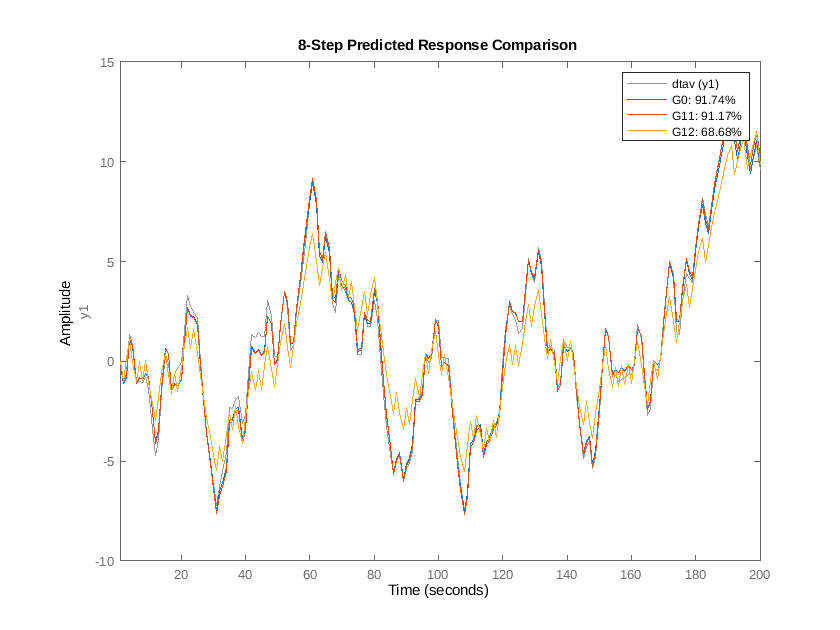

dta = iddata(y1, u1, 1);
dtav = iddata(y1v, u1v, 1);
figure
compare(dtav, G0, G11, G12, 8)

Residual analysis, using ARX models estimated with the sysid toolbox.

G11a = arx(dta, [1, 2, 1])

G11a =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.903 z^-1                            
                                                   
  B(z) = 1.002 z^-1 + 0.8282 z^-2                  
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=2   nk=1
   Number of free coefficients: 3
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "dta".   
Fit to estimation data: 94.43% (prediction focus)
FPE: 0.04142, MSE: 0.0394                        


G12a = arx(dta, [1, 2, 0])

G12a =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.9542 z^-1                           
                                                   
  B(z) = 0.06956 + 1.036 z^-1                      
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=2   nk=0
   Number of free coefficients: 3
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using ARX on time domain data "dta".  
Fit to estimation data: 76.9% (prediction focus)
FPE: 0.7064, MSE: 0.6787                        


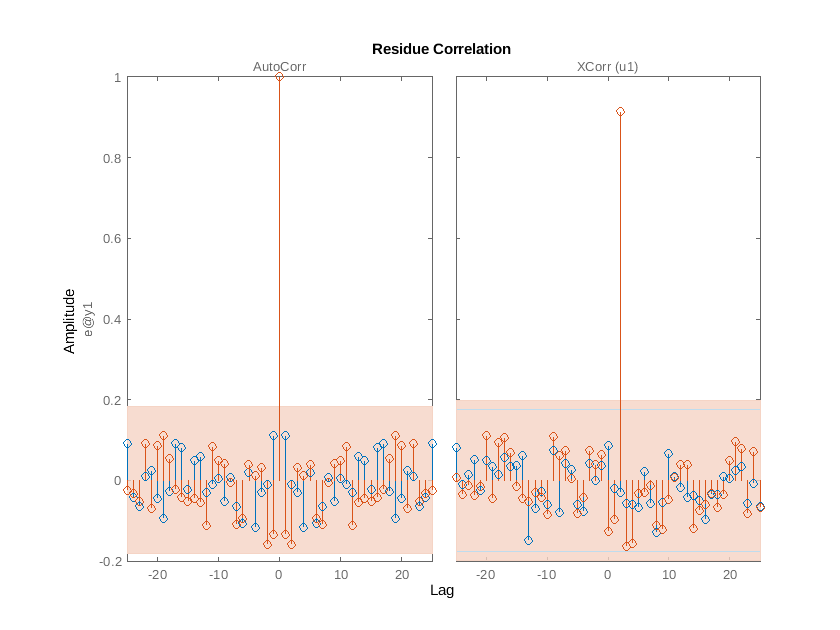

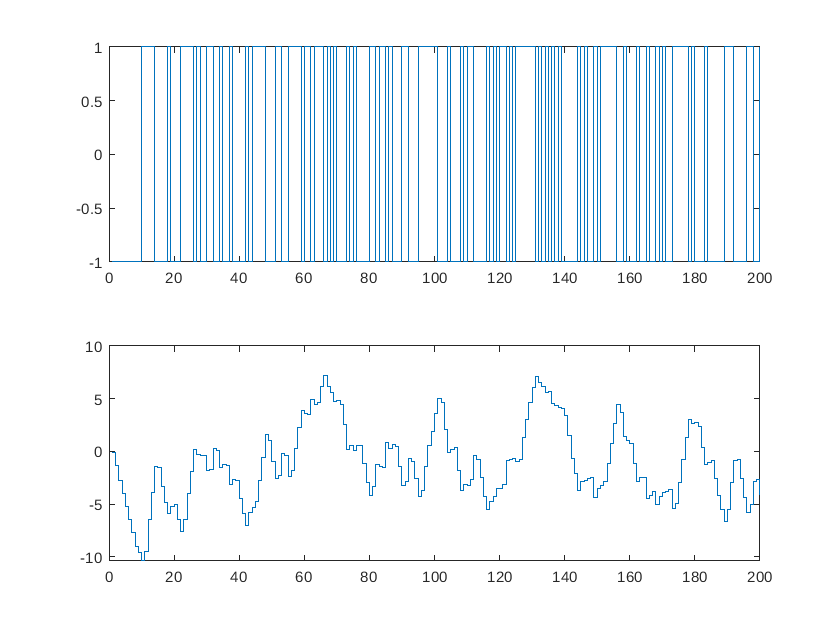

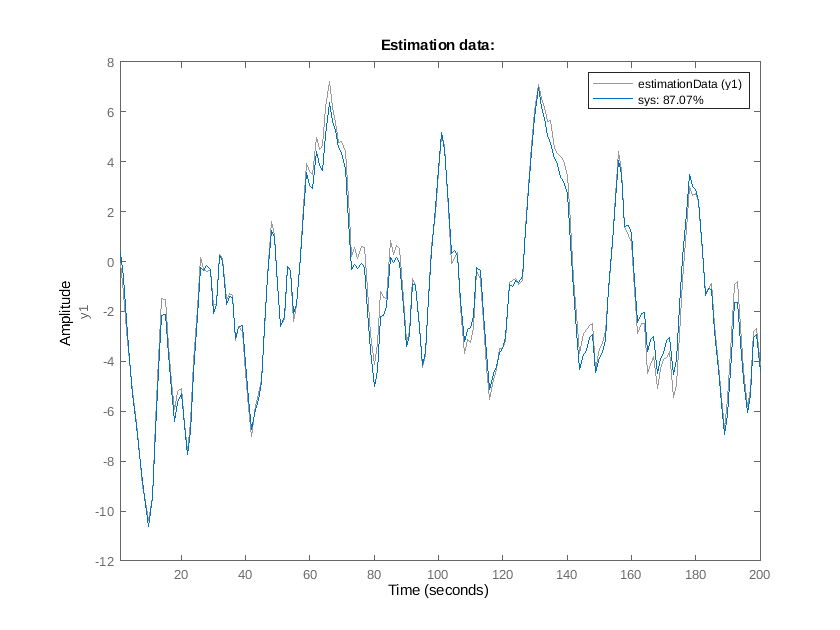

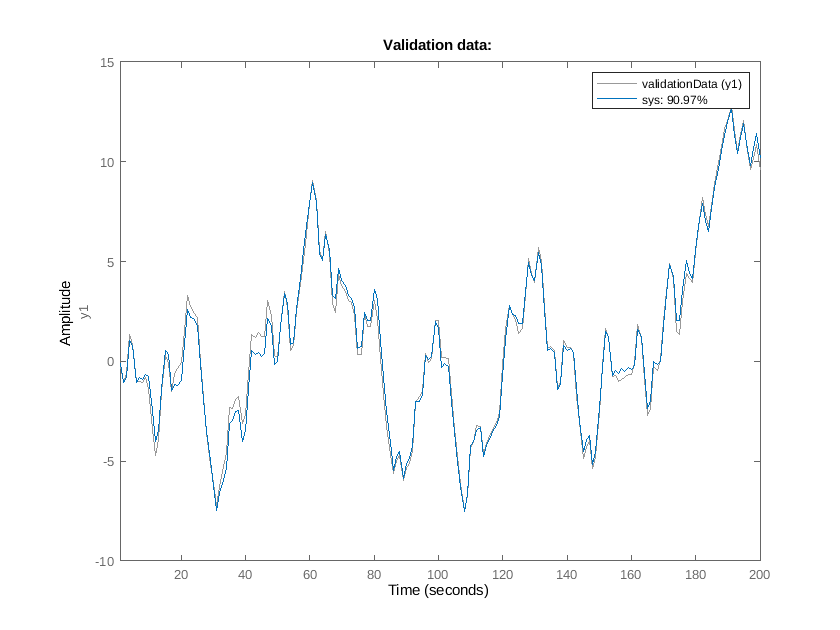

figure
resid(dtav, G11a, G12a)